# HW2 code （Reference)

% For EE101 Homework2 (2021-2020 Fall)
% Author: Liu Anji
clear;clf;

## Q2

E_inc = 67;
theta_deg = 0:30:90;
theta = (0:30:90) / 180 * pi;
E_scat = E_inc ./(1 + E_inc/511*(1 - cos(theta)))

E_scat =    67.0000   65.8434   62.8779   59.2336


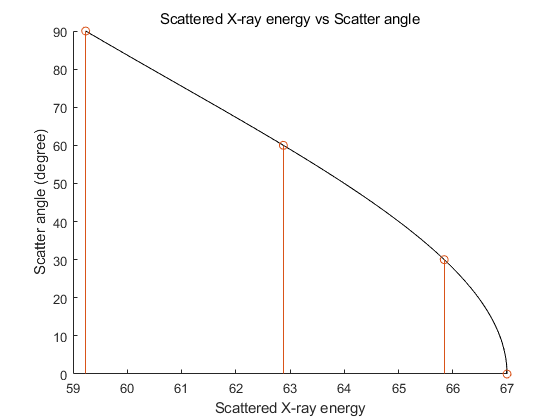


theta_degree = 0:0.1:90;
theta_rad = theta_degree / 180 * pi;
E_scat_rad = E_inc ./(1 + E_inc/511*(1 - cos(theta_rad)));
plot(E_scat_rad, theta_degree,'k')
title("Scattered X-ray energy vs Scatter angle")
xlabel("Scattered X-ray energy")
ylabel("Scatter angle (degree)")
box off
hold on;
stem(E_scat,theta_deg)
hold off;

## Q6

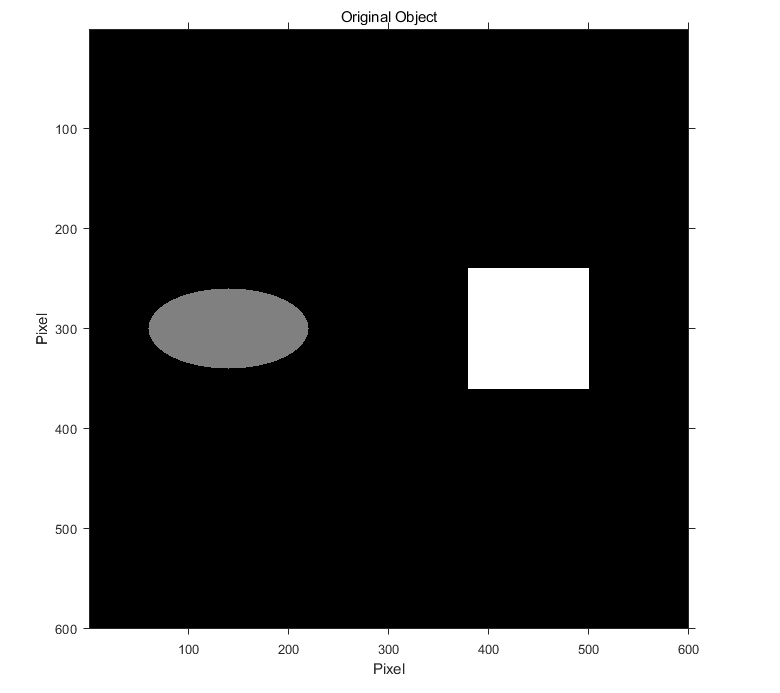

% 图形的构建

h = 600; w = 600; D = 40;
img = zeros(h,w);

% 画出一个正方形
img(h/2-1.5*D : h/2+1.5*D, w/2+2*D:w/2+5*D) = 1; 
[x,y] = meshgrid(1:h, 1:w);

% 画出一个椭圆
img(((y-h/2)/(D)).^2+((x-w/2+4*D)/(2*D)).^2 <= 1) = 0.5;
figure;imshow(img,[]);axis on; title("Original Object");
xlabel("Pixel");ylabel("Pixel");

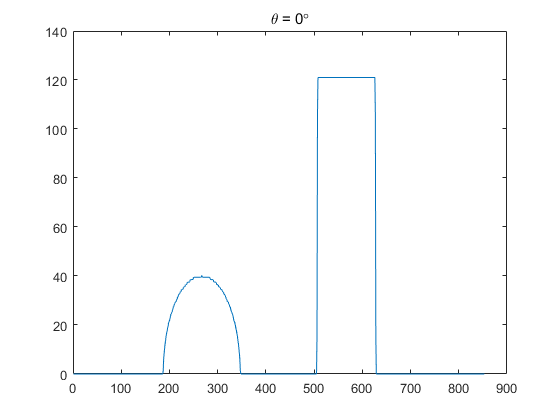

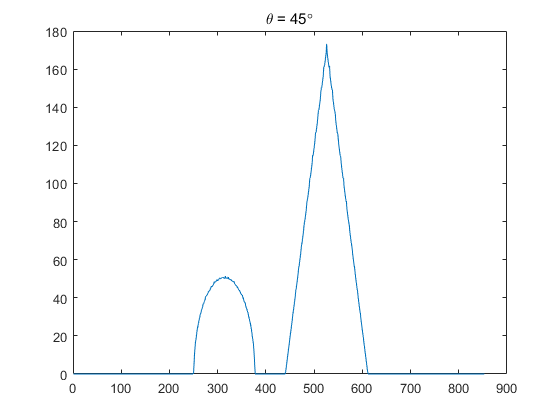

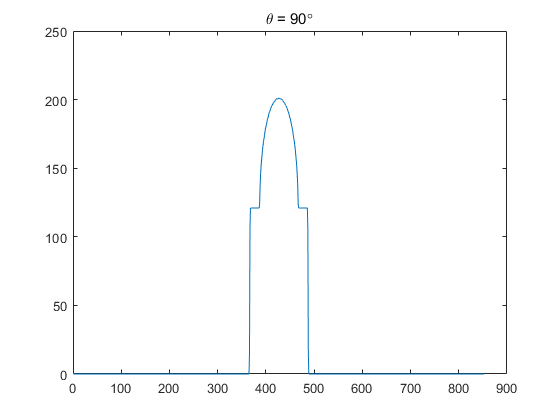

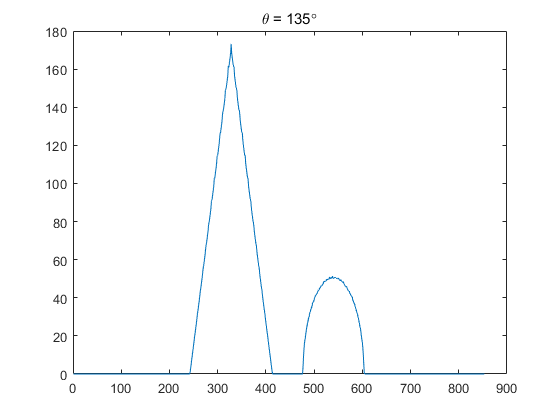

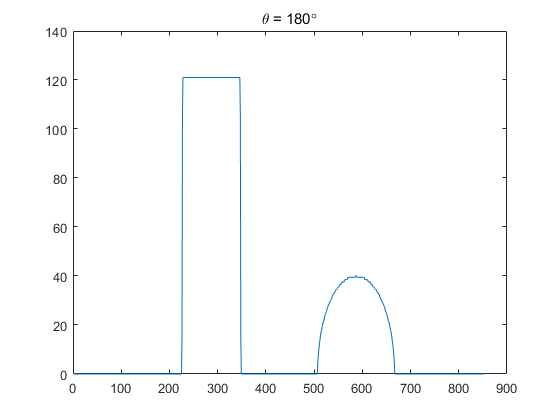

sel_theta = 0:45:180;
len = length(sel_theta);

figure
for i = 1: len
    R_sel = radon(img, sel_theta(i));
    figure
    plot(R_sel)
    title(['\theta = ', num2str((i-1)*45), '\circ'])
end

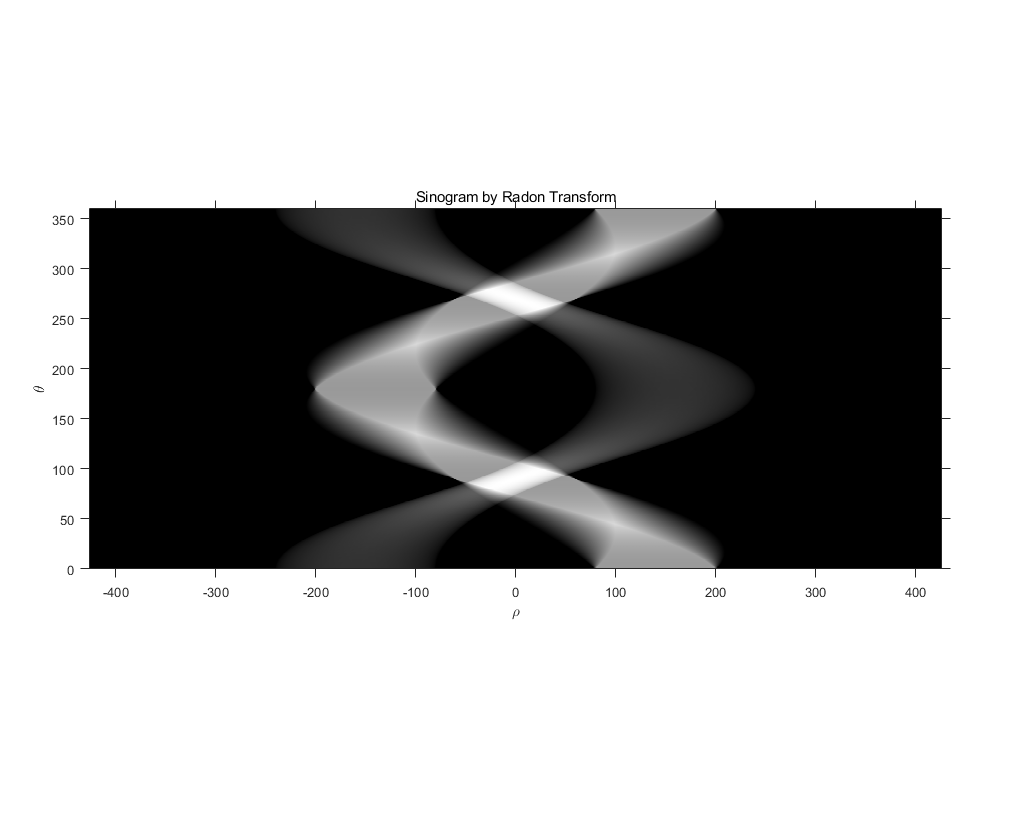


% 对该图像进行雷登变化 并作出正弦图(sinogram)
theta = 0:0.5:359.5;
[R,xp] = radon(img,theta);
R_flip = flipud(R');
figure; imshow(R_flip,[],'XData',xp([1 end]),'YData',[359.5 0]);
axis xy;
axis on;
title("Sinogram by Radon Transform");
xlabel("\rho");ylabel("\theta");

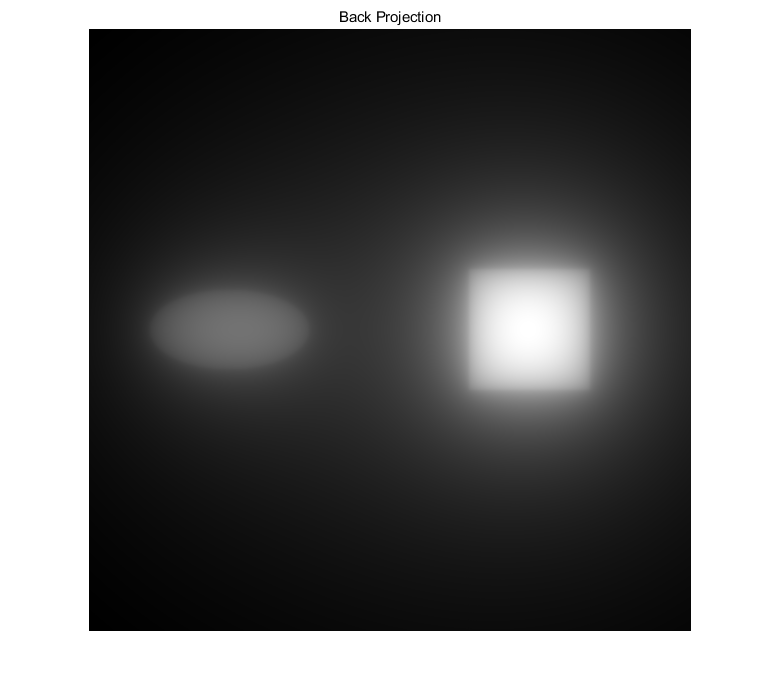

F = iradon(R,theta,'none');
figure;
imshow(F,[])
title("Back Projection")

## Q1

h = 6.62 * 10^(-34); c = 3*10^8; e = 1.6 * 10^(-19);
E_med = 69

E_med = 69

lambda_med = h*c/(E_med*10^3*e)

lambda_med = 1.7989e-11

f_med = c / lambda_med

f_med = 1.6677e+19

lambda_hard = 1.3e-10

lambda_hard = 1.3000e-10

f_hard = c/lambda_hard

f_hard = 2.3077e+18

E_hard = h*c/(lambda_hard * e *10^3)

E_hard = 9.5481

f_soft = 3.846e+17

f_soft = 3.8460e+17

lambda_soft = c/f_soft

lambda_soft = 7.8003e-10

E_soft = h*c/(lambda_soft * e * 10^3)

E_soft = 1.5913

## Q5

u = [0.000028,0.000128,0.00029,0.193,0.196,0.214,0.214,0.537];
u_water = 0.214;
CT_num = (u-u_water)/u_water * 1000